clear, clc, close all

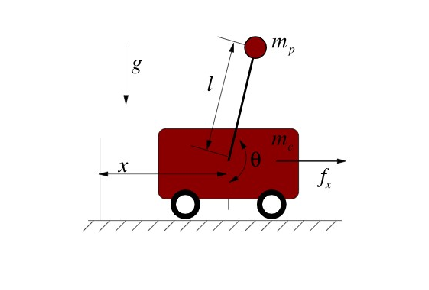

% 2 variable system, cartpole from underactuated
imshow(imread("cartpole_diagram.jpg"))


syms t x(t) t1(t) mc mp l g fx(t)
q = [x; t1]

$$q(t) = \left(\begin{array}{c} x\left(t\right)\\ t_{1}\left(t\right) \end{array}\right)$$

q_dot = diff(q,t)

$$q\_dot(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ \frac{\partial }{\partial t}t_{1}\left(t\right) \end{array}\right)$$

t1_dot = diff(t1,t);
u = fx;

% Create manipulator matrices
% M(q)*q_ddot+C(q,q_dot)*q_dot = B*u + g(q)
M = [mc + mp, mp*l*cos(t1); mp*l*cos(t1), mp*l^2];
C = [0, -mp*l*t1_dot*sin(t1); 0, 0];
B = [1; 0];
tg = [0; -mp*g*l*sin(t1)];

% Solve for symbolic nonlinear q_ddot
q_ddot = simplify(inv(M)*(tg + B*u - C*q_dot));

% Check symbolic derivation against analytical from textbook
x_ddot_analytic = 1/(mc+mp*sin(t1)^2) * (fx + mp*sin(t1) * (l*t1_dot^2+g*cos(t1)))

$$x\_ddot\_analytic(t) = \frac{\mathrm{fx}\left(t\right)+\mathrm{mp}\,\sin\left(t_{1}\left(t\right)\right)\,\left(l\,{\left(\frac{\partial }{\partial t}t_{1}\left(t\right)\right)}^{2}+g\,\cos\left(t_{1}\left(t\right)\right)\right)}{\mathrm{mp}\,{\sin\left(t_{1}\left(t\right)\right)}^{2}+\mathrm{mc}}$$

t_ddot_analytic = 1/(l*(mc+mp*sin(t1)^2)) * (-fx*cos(t1)-mp*l*t1_dot^2*cos(t1)*sin(t1)-(mc+mp)*g*sin(t1))

$$t\_ddot\_analytic(t) = -\frac{l\,\mathrm{mp}\,\cos\left(t_{1}\left(t\right)\right)\,\sin\left(t_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}t_{1}\left(t\right)\right)}^{2}+\cos\left(t_{1}\left(t\right)\right)\,\mathrm{fx}\left(t\right)+g\,\sin\left(t_{1}\left(t\right)\right)\,\left(\mathrm{mc}+\mathrm{mp}\right)}{l\,\left(\mathrm{mp}\,{\sin\left(t_{1}\left(t\right)\right)}^{2}+\mathrm{mc}\right)}$$

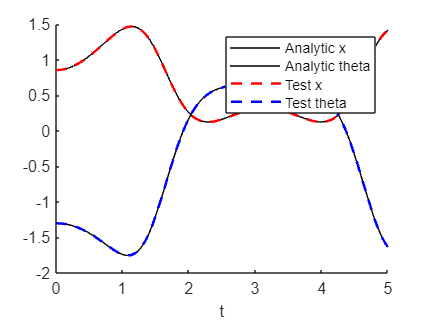


% Arbitrary functions of time
xt(t) = sin(t);
t1t(t) = cos(t);

%Subtitute into both functions
test_x = subs(x_ddot_analytic,[x(t), t1(t), mc, mp, l, g, fx],[xt, t1t, 1, 1, 1, 1, 1]);
test_t = subs(t_ddot_analytic,[x(t), t1(t), mc, mp, l, g, fx],[xt, t1t, 1, 1, 1, 1, 1]);
test_q = subs(q_ddot,[x(t), t1(t), mc, mp, l, g, fx],[xt, t1t, 1, 1, 1, 1, 1]);

% Check that output is the same
figure()
hold on
fplot(test_q,[0,5],'k-')
fplot(test_x,[0,5],'r--','LineWidth',1.5)
fplot(test_t,[0,5],'b--','LineWidth',1.5)
xlabel("t")
legend("Analytic x", "Analytic theta","Test x","Test theta")

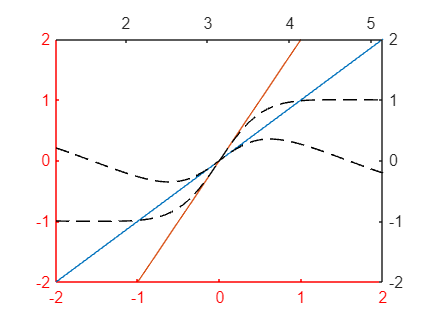

% Now want to linearize the nonlinear equation for acceleration around
% arbitrary joint states q0 = [x0, t10] and input u0 = [fx0]
syms x0 t10 fx0 dx dt1 dfx t1_var fx_var

% f(x,y) = f(x0,y0) + (x-x0)*df/dx|(x0,y0) + (y-y0)*df/dy|(x0,y0)
% f(dx,dy) = dx*df/dx|(x0,y0) + dy*df/dy|(x0,y0), where dx = x-x0, dy=y-y0
q_ddot0 = subs(q_ddot,[t1,fx],[t10,fx0]);
dq_ddot_dx = subs(diff(q_ddot,x),[x,t1,fx],[x0,t10,fx0]);
dq_ddot_dt1 = subs(diff(q_ddot,t1),[x,t1,fx],[x0,t10,fx0]);
dq_ddot_dfx = subs(diff(q_ddot,fx),[x,t1,fx],[x0,t10,fx0]);
q_ddot_lin = q_ddot0 + dx*dq_ddot_dx + dt1*dq_ddot_dt1 + dfx*dq_ddot_dfx;

% Make further analysis easier by setting all constants to 1
q_ddot_lin = simplify(subs(q_ddot_lin,[mc,mp,l,g],[1,1,1,1]));
q_ddot_ti([t1_var,fx_var]) = subs(q_ddot,[t1,fx,mc,mp,l,g],[t1_var,fx_var,1,1,1,1]);

% Plot linearization on nonlinear plot above, which in this case
% only depends on theta and fx at a given time
dq = 2;
t1_0 = pi;
fx_0 = 0;

q_ddot_lin_plot_t1(dt1) = subs(q_ddot_lin,[dfx,t10,fx0],[0,t1_0,fx_0]);
test_q_lin_t1(t1_var) = subs(q_ddot_ti,fx_var,fx_0);
figure()
t = tiledlayout(1,1);
% Create axis for linearized system
ax1 = axes(t);
fplot(q_ddot_lin_plot_t1,[-dq,dq])
ax1.XColor = 'r';
ax1.YColor = 'r';
ax1.YLim = [-2,2];
hold on
ax2 = axes(t);
fplot(test_q_lin_t1,[t1_0-dq,t1_0+dq],'k--')
ax2.XAxisLocation = 'top';
ax2.YAxisLocation = 'right';
ax2.YLim = [-2,2];
ax2.Color = 'none';
ax1.Box = 'off';
ax2.Box = 'off';

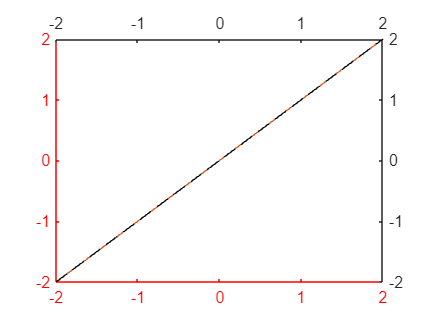


q_ddot_lin_plot_fx(dfx) = subs(q_ddot_lin,[dt1,t10,fx0],[0,t1_0,fx_0]);
test_q_lin_fx(fx_var) = subs(q_ddot_ti,t1_var,t1_0);
figure()
t = tiledlayout(1,1);
% Create axis for linearized system
ax1 = axes(t);
fplot(q_ddot_lin_plot_fx,[-dq,dq])
ax1.XColor = 'r';
ax1.YColor = 'r';
ax1.YLim = [-2,2];
hold on
ax2 = axes(t);
fplot(test_q_lin_fx,[fx_0-dq,fx_0+dq],'k--')
ax2.XAxisLocation = 'top';
ax2.YAxisLocation = 'right';
ax2.YLim = [-2,2];
ax2.Color = 'none';
ax1.Box = 'off';
ax2.Box = 'off';

% Now we need to assemble the linearized equation into A and B matrices for
% state space representation x_dot = Ax + Bu

% In this example, x - x0 = [delta_x, delta_theta, delta_x_dot, delta_theta_dot]
n = size(q(1),1); % n joint states
m = size(u(1),1); % m control inputs
A_lin = sym(zeros(2*n));
B_lin = sym(zeros(2*n,m));
A_lin(1:n,n+1:end) = eye(n); % d/dt of q is just q_dot

% Now need to collect coefficients of the linearized equation to insert
% into A_lin and B_lin
% Since it is now linear with respect to the state variables, can just get
% the coefficients with respect to each one. Can ignore offset since x-x0
% removes dependence on f(x0)
q_lin_body = formula(q_ddot_lin);

[ct1,tt1] = coeffs(q_lin_body(1),dt1);
[ct2,tt2] = coeffs(q_lin_body(2),dt1);
t_coeff = [ct1(1); ct2(1)];

% x_coeffs are zero, but would need for a general expression
x_coeff = [0; 0];

[cu1,tu1] = coeffs(q_lin_body(1),dfx);
[cu2,tu2] = coeffs(q_lin_body(2),dfx);
u_coeff = [cu1(1); cu2(1)];

% Now we can set the corresponding entries of A_lin and B_lin relative to the
% coefficients 
A_lin(n+1:end,1:n) = [x_coeff, t_coeff];
B_lin(n+1:end) = u_coeff;

%TODO Do I need to include velocity terms in linearization?

% Now we can test an LQR controller around the stable set point of 
% [x0, t10] = [0, pi]
x_ss = 0;
t1_ss = pi;
u_ss = 0;
C_ss = [0 1 0 0];
A_ss = double(subs(A_lin,[t10,fx0],[t1_ss,u_ss]))

A_ss =      0     0     1     0
     0     0     0     1
     0     1     0     0
     0     2     0     0


B_ss = double(subs(B_lin,[t10,fx0],[t1_ss,u_ss]))

B_ss =      0
     0
     1
     1


sys = ss(A_ss, B_ss,C_ss,0);
rank(ctrb(sys))

ans = 4

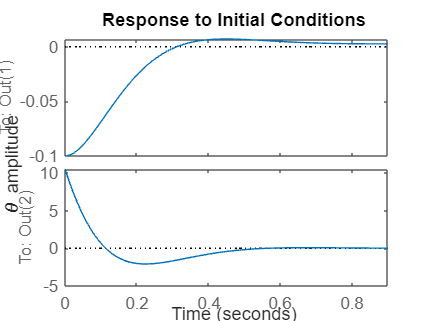

Q = diag([1, 1/.01^2, 0, 0]);
R = 1;
K = lqr(sys,Q,R);  
C_obs = [0 1 0 0; -K];
sysc = ss(A_ss-B_ss*K,B_ss,C_obs,0);
figure()
i0 = [0;-.1;0;0];
initial(sysc,i0)
ylabel("\theta amplitude")


% Looks like this is working correctly
% Now test linearize_around_state function

[A_lin_test, B_lin_test,dq,du] = linearize_around_state(M,C,B,tg,q,u);
A_lin_test = subs(A_lin_test,[mc,mp,l,g],[1,1,1,1]);
B_lin_test = subs(B_lin_test,[mc,mp,l,g],[1,1,1,1]);
A_lin_test = subs(A_lin_test,[t1,fx],[t10,fx0]);
A_lin_test = double(subs(A_lin_test,[t10,fx0],[t1_ss,u_ss]))

A_lin_test =      0     0     1     0
     0     0     0     1
     0     1     0     0
     0     2     0     0


B_lin_test = subs(B_lin_test,[t1,fx],[t10,fx0]);
B_lin_test = double(subs(B_lin_test,[t10,fx0],[t1_ss,u_ss]))

B_lin_test =      0
     0
     1
     1


% Test lqr controller on nonlinear model
tspan = [0,5];
y0 = [0;pi+0.1;0;0];
% Controlled
[t,y] = ode45(@(t,y) nonlinear_lqr(t,y,K,x_ss,t1_ss,u_ss), tspan, y0);
% Not Controlled
[t2,y2] = ode45(@(t2,y2) nonlinear_lqr(t2,y2,[0,0,0,0],x_ss,t1_ss,u_ss), tspan, y0);
% Starts far away from steady state
y01 = [0;pi+1;0;0];
[t3,y3] = ode45(@(t3,y3) nonlinear_lqr(t3,y3,K,x_ss,t1_ss,u_ss), tspan, y01);

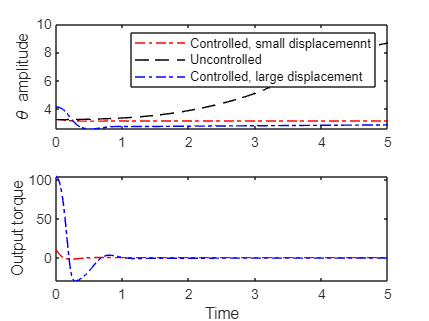

% Plot responses
figure()
subplot(2,1,1)
plot(t1,y1(:,2),'r-.')
hold on
plot(t2,y2(:,2),'k--')
plot(t3,y3(:,2),'b-.')
ylabel('\theta amplitude')
legend('Controlled, small displacemennt', 'Uncontrolled','Controlled, large displacement')
subplot(2,1,2)
yss = [x_ss,t1_ss,0,0];
plot(t1,K*(y1-yss)','r-.')
hold on
plot(t3,K*(y3-yss)','b-.')
xlabel('Time')
ylabel('Output torque')

% Now need to try with a trajectory
